# FFT Applications - Basic Principles of FFT Usage

## DFT/FFT definition

FFT (Fast Fourier Transform) is an algorithm for fast computation of the DFT (Discrete Fourier Transform), defined as:

$X(kf_0)=\frac{1}{N} \sum_{n=0}^{N-1} x(n) e^{-j 2\pi \frac{kf_0}{f_s}n}=\frac{1}{N} \sum_{n=0}^{N-1} x(n) e^{-j \frac{2\pi}{N}kn}, \quad k=0,1,2,...,N-1$.

In the FFT the same  is computed as in DFT but in a faster way. The result is the same!  

## Analyzed signal

Let's assume that the N-samples long fragment of single sinusoidal signal $x(t)=\sin \left( 2\pi f_x t \right)$ will be analyzed by us by means of FFT. Run the code for different number of signal samples `N` and different sine repetition frequency `fx` (sine amplitude is constant and equals 1). Observe the signal shape.

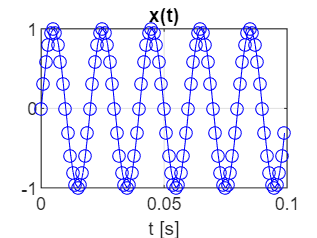

clear all; close all;        % "washing hands"
fs = 1000;                   % sampling ratio (Hz)
N  = 100;                    % number of signal samples, 100 or 1000
dt=1/fs; t=dt*(0:N-1);       % time scaling
f0 = 1/(N*dt);               % fundamental frequency of N-point DFT = fs/N

% Signal
fx=50; x = sin(2*pi*fx*t);   % signal with frequency fx = 25,50,100,125,200,225 Hz
figure; plot(t,x,'bo-'); xlabel('t [s]'); title('x(t)'); grid;

## Typical FFT call

The FFT algorithm is widely implemented and available world-wide, also in Matlab - but without division by $N$ inside the procedure. Therefore this division should be performed after the function call.  Run first two fragments of the Matlab code: now observe signals and absolute value $|X(kf_0)|$of their FFT spectra. Observe that FFT peaks are located close to the signal frequency. Two peaks are seen because:

$\sin (2\pi f_x t) = \frac{e^{j2\pi f_xt}-e^{-j2\pi f_xt}}{2j}$.

The first peak is for the positive frequency $f_x$ while the second one for the negative frequency $-f_x$ (in fact, for its "copy: $f_s-f_x$).

**Analyze the Matlab code**. Show only a fragment of the frequency DFT/FFT spectrum.

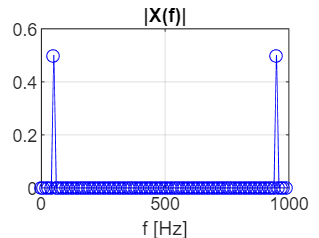

% FFT spectrum
X = fft(x)/N;                % FFT unscaled, for positive and negative frequencies
f = fs/N*(0:N-1);            % frequency axis: df=f0=1/(N*dt)=fs/N
figure; plot(f,abs(X),'bo-'); xlabel('f [Hz]'); title('|X(f)|'); grid;

## Better FFT call

In the simplest FFT usage rectangular window is used for signal fragment shaping and the spectrum is divided by $N$ (summation result of $N$ samples of rectangular window $w(n)=1, \;\; n=1...N$).

The following "tricks" should be used for improving spectral analysis based on FFT.

- We remember from laboratory on DFT & DtFT that** application of another window function** can improve amplitude resolution of the DFT spectrum (i.e. increase side-lobes attenuation of the window spectrum) by the cost of decreasing the frequency DFT resolution (caused by widening the main-lobe of the window spectrum). To counteract this effect, the value of $N$ should be increased before signal windowing (i.e. longer signal fragment should be transformed).

- Since FFT specrum of a real signal is **conjugate symmetric**, it is better to show only the first half of it (for `k=1:N/2+1`).

- Since number of frequency lags/bins in the output DFT/FFT spectrum in equal to number of input signals samples, what caused denser spectrum sampling (its **interpolation**), we can artificially append some zeros to the analyzed signal end. This will not change the resultant spectrum shape, only cause its denser sampling.

**Analyze the below code.** Add more window functions and test their usage. Change side-lobes attenuation `Asl` in the Chebyshev window. Apply different values of `K` (spectrum interpolation order - resulting from number of appended zeros). 

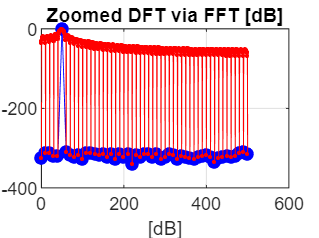

% Better FFT spectrum: 1) with window usage (better amplitude resulution), 2) with zeros appending
% (better spectrum shape due to its interpolation), 3) showing only half of the spectrum scaled by 2
K = 20;                      % interpolation order
w1 = rectwin(N);             % retangular window
w2 = chebwin(N,100);         % Chebyshev window: Asl=60,80,100,120
w = w1;                      % window choice: w1, w2, ...
x = x.*w';                   % signal windowing
X  = fft(x,N);               % without appended zeros at signal end
Xz = fft(x,K*N);             % with these zeros; the same: Xz = fft([x,zeros(1,(K-1)*N)])/sum(w);
fz = fs/(K*N)*(0:K*N-1);     % new frequency axis for signal with zeros
figure                       % DFT spectrum inspection                      
n = 1:N/2+1; nz = 1:K*N/2+1; % only first HALF of the spectrum but scaled by 2
plot(f(n),  20*log10(2*abs(X(n))  /sum(w)),'bo-',...
     fz(nz),20*log10(2*abs(Xz(nz))/sum(w)),'r.-','MarkerFaceColor','b');
xlabel('f (Hz)'); xlabel('[dB]'); title('Zoomed DFT via FFT [dB]'); grid;